# Plot Gas Prices

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the gas prices data and displays the variables.

countries = readmatrix("./data/gPrices.xlsx", "Sheet", "countries", "OutputType", "string");
prices = readmatrix("./data/gPrices.xlsx", "Sheet", "prices");
Year = readmatrix("./data/gPrices.xlsx", "Sheet", "Year");
whos

  Name             Size            Bytes  Class      Attributes

  Year            19x1               152  double               
  countries        1x10              668  string               
  ctry             1x1               150  string               
  ctryPrices      19x0                 0  double               
  errMsg           1x1               198  string               
  idx              1x10               10  logical              
  prices          19x10             1520  double               



ctry = "Canada"

ctry = "Canada"

This code extracts the relevant data for a country.

idx = strcmp(ctry, countries);
ctryPrices = prices(:, idx)

ctryPrices =     1.8700
    1.9200
    1.7300
    1.5700
    1.4500
    1.5300
    1.6100
    1.6200
    1.3800
    1.5200


## Data Check

When you ask for user input, you may want to communicate information to the user based on the input they provided. In this practice, you will use an `if-elseif` statement to notify the user if they selected an invalid country or if the selected country has missing data.

You can change the input to `Australia` and run the script and see a plot of the Australian gas prices. However, there is a missing value, `NaN`, in the prices. It would be good to issue a warning message to the user if there is any missing data in the plot.

`if` `condition1`

    `code`

`elseif` `condition2`

    `morecode`

`end`

Check for missing data

if ~any(idx)
    errMsg = "No data available for " + ctry;
    error(errMsg)
elseif any(isnan(ctryPrices))
    warnMsg = "Missing values in price data for " + ctry + ".";
    warning(warnMsg)
end

This code plots the data.

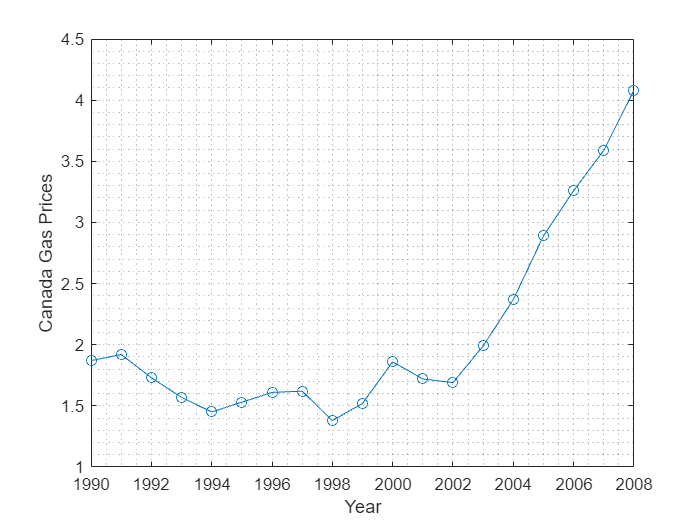

plot(Year,ctryPrices, "o-")
grid minor
xlabel("Year")
ylabel(ctry + " Gas Prices")